L=24e-6

L = 2.4000e-05

b=1e-6

b = 1.0000e-06

h=0.2e-6

h = 2.0000e-07

E=1.9e13

E = 1.9000e+13

y=8e-6

y = 8.0000e-06

I=b*h^3/12

I = 6.6667e-28

F=b*E*(h^3)*y/4/(L^3)

F = 2.1991e-05

sigma=3*E*y*h/2/(L^2)

sigma = 7.9167e+10

sigma=6*F*L/b/h^2

sigma = 7.9167e+10

theta=asin(y/0.85/L)

theta = 0.4030

x=0.15*L+0.85*L*cos(theta)

x = 2.2366e-05

F=2.25*E*I*theta/L/L/0.85/cos(theta)

F = 2.5500e-05

2.25*E*I*theta/L/L

ans = 1.9939e-05

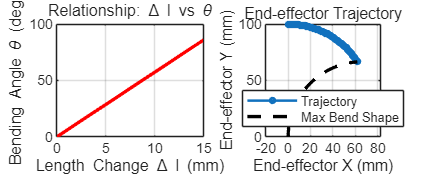

clc; clear; close all;

%1. 参数设置
L0 = 100;       % 中心骨架初始长度 (mm)
d = 5;          % 绳索离中心的距离 (mm)
dl_max = 15;    % 最大长度变化量 (mm)

%2. 不同绳长差变化下计算末端位置和弯折角度
dl_series = linspace(0, dl_max, 50); 
theta = dl_series ./ 2/ d;  % 角度 theta = delta_l / d
x = zeros(size(theta));
y = zeros(size(theta));

% 处理theta = 0 
for i = 1:length(theta)
    if theta(i) == 0
        x(i) = 0;
        y(i) = L0;
    else
        R = L0 / theta(i);
        x(i) = R * (1 - cos(theta(i)));
        y(i) = R * sin(theta(i));
    end
end

%3. 绘图分析
figure('Color','w','Position',[100 100 1000 400]);

% 图1：delta_l vs theta
subplot(1,2,1);
plot(dl_series, rad2deg(theta), 'LineWidth', 2, 'Color', 'r');
grid on;
xlabel('Length Change \Delta l (mm)');
ylabel('Bending Angle \theta (deg)');
title('Relationship: \Delta l vs \theta');
% 图2：末端轨迹 (x, y)
subplot(1,2,2);
plot(x, y, 'o-', 'MarkerSize', 3, 'LineWidth', 1.5);
grid on; axis equal;
xlabel('End-effector X (mm)');
ylabel('End-effector Y (mm)');
title('End-effector Trajectory');
hold on;

% 绘制机构形态示例 (取最大弯曲处)
R_end = L0 / theta(end);
phi = linspace(0, theta(end), 50);
arc_x = R_end * (1 - cos(phi));
arc_y = R_end * sin(phi);
plot(arc_x, arc_y, 'k--', 'LineWidth', 2);
legend('Trajectory', 'Max Bend Shape', 'Location', 'best');

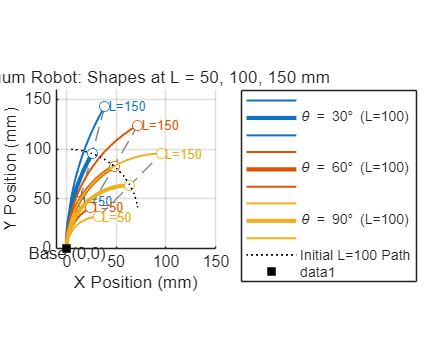

clc; clear; close all;

%1. 参数设置
L_init = 100;               % 初始绳长 (mm)
L_min = 50;                 % 长度下限 (mm)
L_max = 150;                % 长度上限 (mm)
theta_degrees = [30, 60, 90]; % 选取三个弯折角度进行观察
colors = lines(length(theta_degrees)); 

figure('Color','w','Position',[100 100 1000 800]);
hold on; grid on; axis equal;

%2. 绘制
L_critical = [L_min, L_init, L_max]; % 需要绘制形状的三个关键长度

for k = 1:length(theta_degrees)
    curr_theta_deg = theta_degrees(k);
    curr_theta_rad = deg2rad(curr_theta_deg);
    
    % --- A. 绘制末端随长度变化的射线轨迹 ---
    L_traj = linspace(L_min, L_max, 50);
    x_traj = (L_traj ./ curr_theta_rad) .* (1 - cos(curr_theta_rad));
    y_traj = (L_traj ./ curr_theta_rad) .* sin(curr_theta_rad);
    plot(x_traj, y_traj, '--', 'Color', [0.5 0.5 0.5], 'HandleVisibility', 'off');
    
    % --- B. 绘制三个关键长度下的机构形状 ---
    for j = 1:length(L_critical)
        L_curr = L_critical(j);
        R_curr = L_curr / curr_theta_rad;
        
        % 计算弧线形状
        phi = linspace(0, curr_theta_rad, 50);
        shape_x = R_curr * (1 - cos(phi));
        shape_y = R_curr * sin(phi);
        
        % 设置线宽和透明度：初始长度加粗，两端稍细
        if L_curr == L_init
            lw = 2.5; alpha_val = 1.0;
            label = ['\theta = ', num2str(curr_theta_deg), '° (L=100)'];
        else
            lw = 1.2; alpha_val = 0.6;
            label = ''; % 不重复在图例显示
        end
        
        % 绘制形状
        p = plot(shape_x, shape_y, 'Color', [colors(k,:) alpha_val], ...
            'LineWidth', lw, 'DisplayName', label);
        
        % 绘制末端点并标注长度
        plot(shape_x(end), shape_y(end), 'o', 'MarkerSize', 6, ...
            'MarkerEdgeColor', colors(k,:), 'MarkerFaceColor', 'w', 'HandleVisibility', 'off');
        
        % 在 50mm 和 150mm 的末端添加文本标注
        if L_curr ~= L_init
            text(shape_x(end), shape_y(end), sprintf(' L=%d', L_curr), ...
                'FontSize', 8, 'Color', colors(k,:));
        end
    end
end

%3. 绘制 L=100mm 原始绳长的参考线
th_fine = deg2rad(linspace(5, 120, 100));
plot((L_init./th_fine).*(1-cos(th_fine)), (L_init./th_fine).*sin(th_fine), ...
    'k:', 'LineWidth', 1, 'DisplayName', 'Initial L=100 Path');

%4. 图表装饰 
xlabel('X Position (mm)');
ylabel('Y Position (mm)');
title('Continuum Robot: Shapes at L = 50, 100, 150 mm');
legend('Location', 'northeastoutside');
xlim([-10 150]); ylim([0 160]);

% 标注
plot(0,0,'ks','MarkerFaceColor','k');
text(0,-5,'Base (0,0)','HorizontalAlignment','center');